# Mehdi Muzaffari - MAE 674 - Project 1

## dynamic of double pendulum

clc
clear;
close all;

dt = 0.01;
num_steps = 5000;
time = (0:num_steps-1);

theta1 = pi/4;
theta1_dot = 0;
theta2 = pi/6;
theta2_dot = 0;

theta1_history = zeros(1, num_steps);
theta1_dot_history = zeros(1, theta2_dot);
theta2_history = zeros(1, num_steps);
theta2_dot_history = zeros(1, num_steps);

theta1_history(1) = theta1;
theta1_dot_history(1) = theta1_dot;
theta2_history(1) = theta2;
theta2_dot_history(1) = theta2_dot;

## euler integration

for k = 2:num_steps

[theta1_ddot, theta2_ddot] = dynamic(theta1, theta1_dot, theta2, theta2_dot);

theta1_dot = theta1_dot + theta1_ddot * dt;
theta1 = theta1 + theta1_dot * dt;

theta2_dot = theta2_dot + theta2_ddot * dt;
theta2 = theta2 + theta2_dot * dt;

theta1_history(k) = theta1;
theta1_dot_history(k) = theta1_dot;
theta2_history(k) = theta2;
theta2_dot_history(k) = theta2_dot;

end

## plot

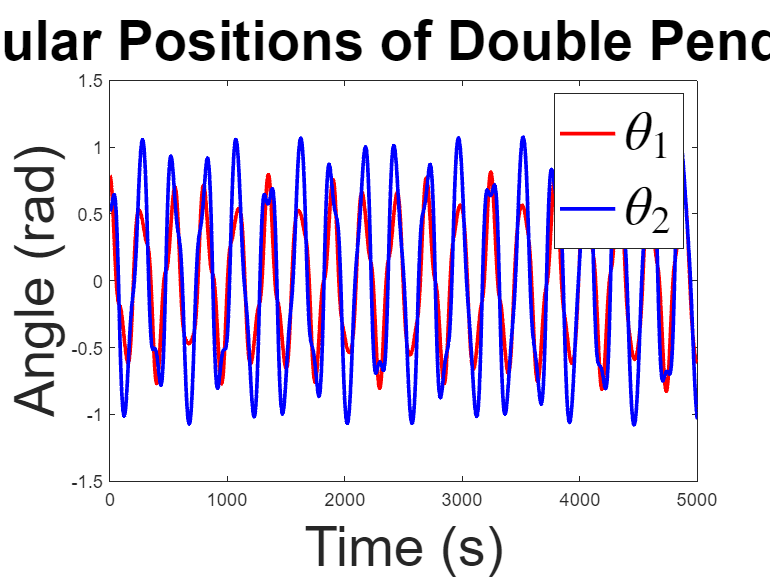

figure;
plot(time, theta1_history, 'DisplayName', '$\theta_1$', 'LineWidth', 2.0, 'Color', 'r');
hold on
plot(time, theta2_history, 'DisplayName', '$\theta_2$', 'LineWidth', 2.0, 'Color', 'b');
xlabel('Time (s)', 'FontSize', 30);
ylabel('Angle (rad)', 'FontSize', 30);
legend('Interpreter', 'latex', 'FontSize', 30);
title('Angular Positions of Double Pendulum', 'FontSize', 30);
hold off

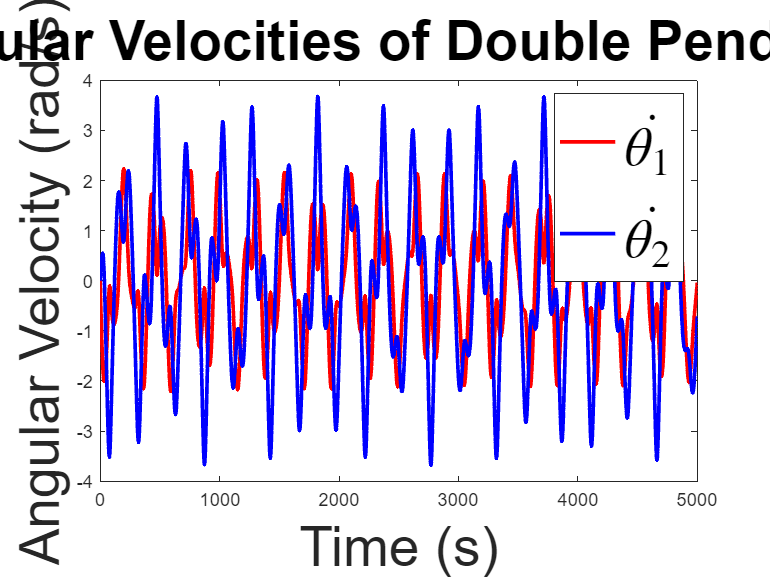

figure;
plot(time, theta1_dot_history, 'DisplayName', '$\dot{\theta_1}$', 'LineWidth', 2.0, 'Color', 'r');
hold on
plot(time, theta2_dot_history, 'DisplayName', '$\dot{\theta_2}$', 'LineWidth', 2.0, 'Color', 'b');
xlabel('Time (s)', 'FontSize', 30);
ylabel('Angular Velocity (rad/s)', 'FontSize', 30);
legend('Interpreter', 'latex', 'FontSize', 30);
title('Angular Velocities of Double Pendulum', 'FontSize', 30);
hold off

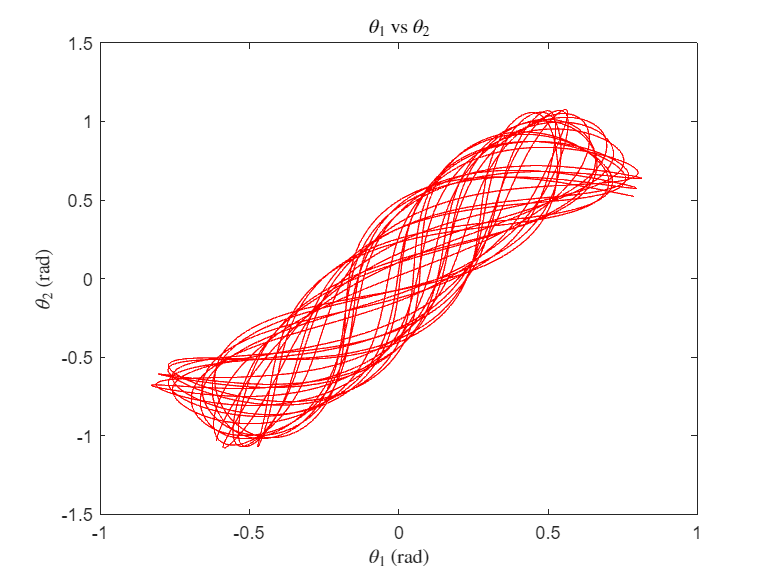

figure;
plot(theta1_history, theta2_history, 'LineWidth', 0.05, 'Color', 'r');
xlabel('$\theta_1$ (rad)', 'Interpreter', 'latex');
ylabel('$\theta_2$ (rad)', 'Interpreter', 'latex');
title('$\theta_1$ vs $\theta_2$', 'Interpreter', 'latex');

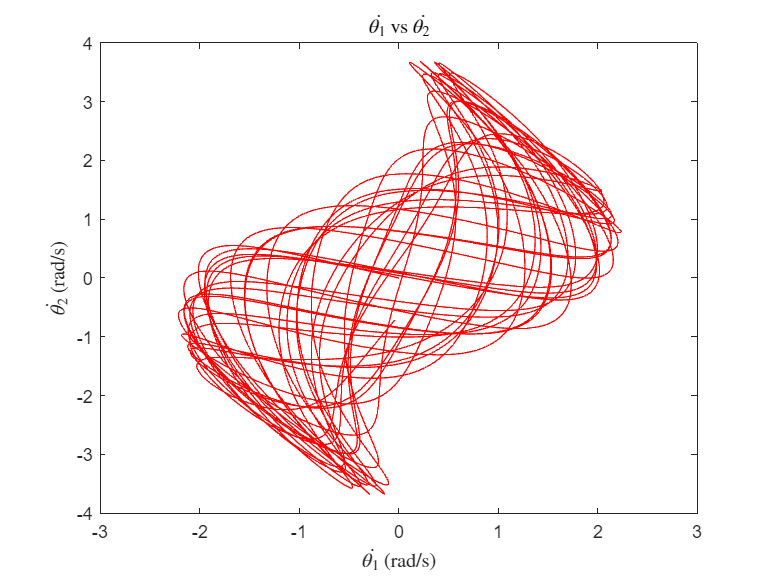

figure;
plot(theta1_dot_history, theta2_dot_history, 'LineWidth', 0.05, 'Color', 'r');
xlabel('$\dot{\theta_1}$ (rad/s)', 'Interpreter', 'latex');
ylabel('$\dot{\theta_2}$ (rad/s)', 'Interpreter', 'latex');
title('$\dot{\theta_1}$ vs $\dot{\theta_2}$', 'Interpreter', 'latex');

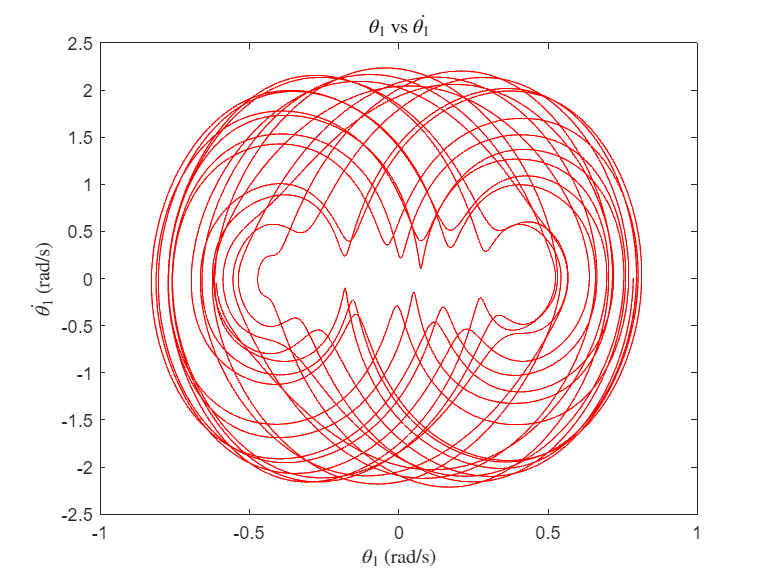

figure;
plot(theta1_history, theta1_dot_history, 'LineWidth', 0.05, 'Color', 'r');
xlabel('$\theta_1$ (rad/s)', 'Interpreter', 'latex');
ylabel('$\dot{\theta_1}$ (rad/s)', 'Interpreter', 'latex');
title('$\theta_1$ vs $\dot{\theta_1}$', 'Interpreter', 'latex');

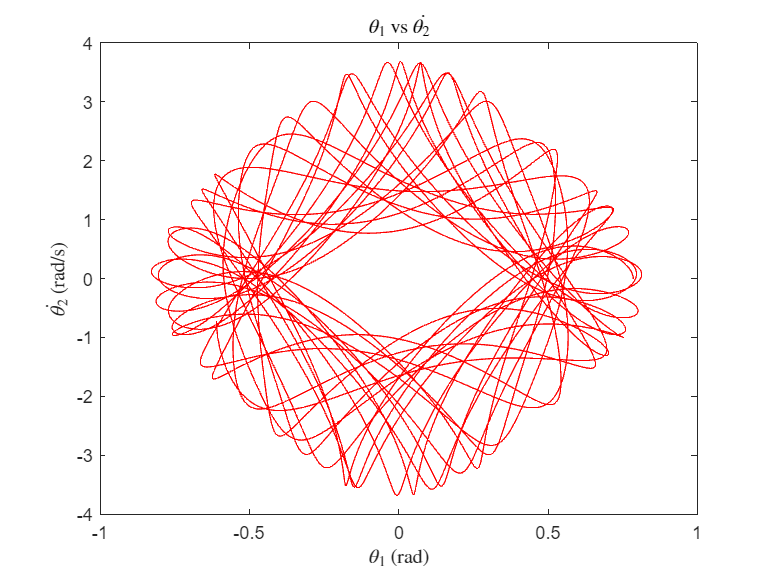

figure;
plot(theta1_history, theta2_dot_history, 'LineWidth', 0.05, 'Color', 'r');
xlabel('$\theta_1$ (rad)', 'Interpreter', 'latex');
ylabel('$\dot{\theta_2}$ (rad/s)', 'Interpreter', 'latex');
title('$\theta_1$ vs $\dot{\theta_2}$', 'Interpreter', 'latex');

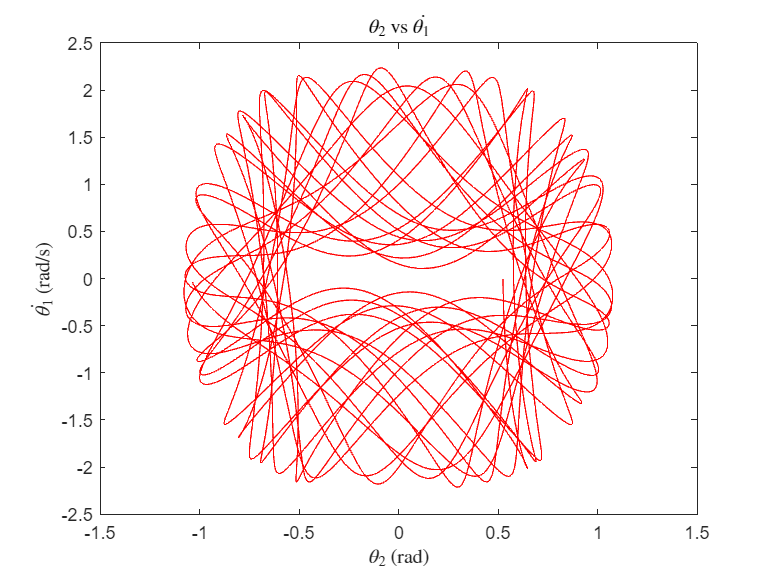

figure;
plot(theta2_history, theta1_dot_history, 'LineWidth', 0.05, 'Color', 'r');
xlabel('$\theta_2$ (rad)', 'Interpreter', 'latex');
ylabel('$\dot{\theta_1}$ (rad/s)', 'Interpreter', 'latex');
title('$\theta_2$ vs $\dot{\theta_1}$', 'Interpreter', 'latex');

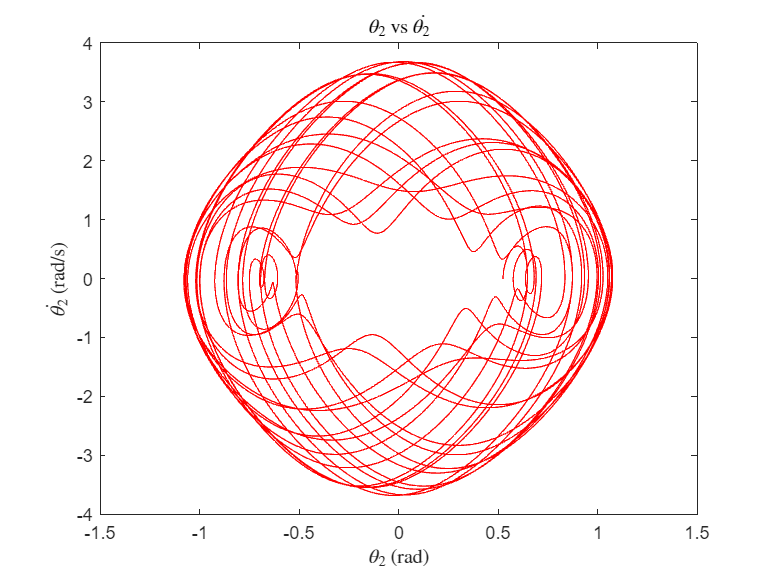

figure;
plot(theta2_history, theta2_dot_history, 'LineWidth', 0.05, 'Color', 'r');
xlabel('$\theta_2$ (rad)', 'Interpreter', 'latex');
ylabel('$\dot{\theta_2}$ (rad/s)', 'Interpreter', 'latex');
title('$\theta_2$ vs $\dot{\theta_2}$', 'Interpreter', 'latex');